clear
clc
n=40; %numero de cargas en la distribucion
size1=input('Introduce la longitud deseado del conductor:')  %Tamaño del 1er conductor 1

size1 = 3

size2=input('Introduce la longitud deseado del 2do conductor:') %Tamaño 2do conductor 

size2 = 2

q1=input('Introduce el valor de una carga individual del primer conductor:')

q1 = 3

q2=input('Introduce el valor de una carga individual del segundo conductor:')

q2 = -4

lambda=(n*q1)/(size1);
lambda1=(n*q2)/(size2);
sizey=input('Introduce la distancia entre capacitores:')

sizey = 3

f1=@(x)sizey./2;
f2=@(x)-sizey./2;


%calculo y graficación Cargas Puntuales en los capacitores

xqn1=linspace(-size1/2,size1/2,n); %Coordenadas x 
yqn1=ones(length(xqn1))*f1(xqn1); %Cooredenadas y
qn1=ones(size(xqn1)).*lambda; %Cargas*lambda


xqn2=linspace((-size2/2),size2/2,n);
yqn2=ones(length(xqn2))*f2(xqn2);
qn2=ones(size(xqn2))*lambda1;

%meshgid

x=linspace(-size1/2-2,size1/2+2,n);
y=linspace(-sizey/2-2,sizey/2+2,n);
[X,Y]=meshgrid(x,y);
x3=X;
y3=Y;

distx=[];
disty=[];
num1=[];
num2=[];
k=9000000000; 
p=1;
for i=1:length(xqn1) %Distancias en X  de cargas y puntos y Y
    distx=[distx;x3-xqn1(i)];
    disty=[disty;y3-yqn1(i)];
    num1=[num1;k.*qn1(i).*distx(p:i*length(x),1:length(x))];
    num2=[num2;k.*qn1(i).*disty(p:i*length(x),1:length(x))];
    p=(i*length(x))+1 ; 
end

denom=(distx.^2+disty.^2).^1.5;
Exx=num1./denom;
Ex=zeros(length(x),length(x));
m=1;
for q=1:length(x)
    Ex=Ex+Exx(m:q*length(x),1:length(x));%Magnnitudes en 
    m=q*length(x)+1;
end
Eyy=num2./denom;
Ey=zeros(length(x),length(x));

a=1;
for r=1:length(x)
    Ey=Ey+Eyy(a:r*length(x),1:length(x));
    a=r*length(x)+1;
end

%Parte negativa
distx2=[];
disty2=[];
num3=[];
num4=[];
h=1

h = 1

for i2=1:length(xqn2)
    distx2=[distx2;x3-xqn2(i2)];
    disty2=[disty2;y3-yqn2(i2)];
    num3=[num3;k.*qn2(i2).*distx2(h:i2*length(x),1:length(x))];
    num4=[num4;k.*qn2(i2).*disty2(h:i2*length(x),1:length(x))];
    h=(i2*length(x))+1  ;
end

denom2=(distx2.^2+disty2.^2).^1.5;
Exx2=num3./denom2;
Ex2=zeros(length(x),length(x));

u=1;
for i3=1:length(x)
    Ex2=Ex2+Exx2(u:i3*length(x),1:length(x));
    u=i3*length(x)+1;
end
Eyy2=num4./denom2;
Ey2=zeros(length(x),length(x));
v=1;
for i4=1:length(x)
    Ey2=Ey2+Eyy2(v:i4*length(x),1:length(x));
    v=i4*length(x)+1;
end
%quiver(X,Y,Ex,Ey)
%quiver(X,Y,Ex2,Ey2)
ex=Ex+Ex2;
ey=Ey+Ey2;
chivas=sqrt(ex.^2+ey.^2);
ex1=ex./chivas;
ey1=ey./chivas;

%Grafica vectores unitarios Hold on
%subplot(1,3,1)
figure(1)
quiver(X,Y,ex1,ey1,'k','autoscalefactor',1)
axis equal
hold on
xlim([-size1/2,size1/2])
ylim([-sizey/2,sizey/2])
if qn1(1)>0
    fplot(f1,[-size1/2,size1/2],'r')
    plot(xqn1,yqn1,'r*')
    title('Vectores unitarios')
else
    fplot(f1,[-size1/2,size1/2],'b')
    plot(xqn1,yqn1,'b*')
    title('Vectores unitarios')
end


if qn2(1)>0
    plot(xqn2,yqn2,'r*')
    fplot(f2,[-(size2/2),size2/2],'r')
    title('Vectores unitarios')
else
    plot(xqn2,yqn2,'b*')
    fplot(f2,[-(size2/2),size2/2],'b')
    title('Vectores unitarios')
end

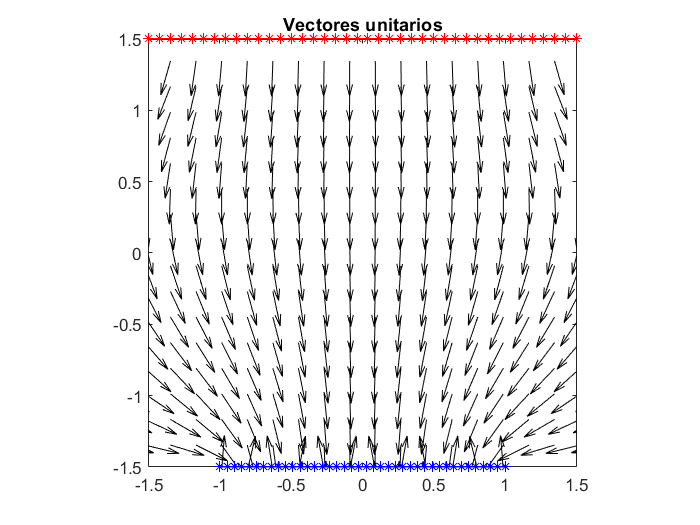

hold off


%Grafica vectores a escala real
%subplot(1,3,2)
figure(2)
quiver(X,Y,ex,ey,'k','autoscalefactor',1)
axis equal
hold on
xlim([-size1/2,size1/2])
ylim([-sizey/2,sizey/2])
if qn1(1)>0
    fplot(f1,[-size1/2,size1/2],'r')
    plot(xqn1,yqn1,'r*')
    title('vectores a escala real')
else
    fplot(f1,[-size1/2,size1/2],'b')
    plot(xqn1,yqn1,'b*')
    title('vectores a escala real')
end

if qn2(1)>0
    plot(xqn2,yqn2,'r*')
    fplot(f2,[-(size2/2),size2/2],'r')
    title('vectores a escala real')
else
    plot(xqn2,yqn2,'b*')
    fplot(f2,[-(size2/2),size2/2],'b')
    title('vectores a escala real')
end

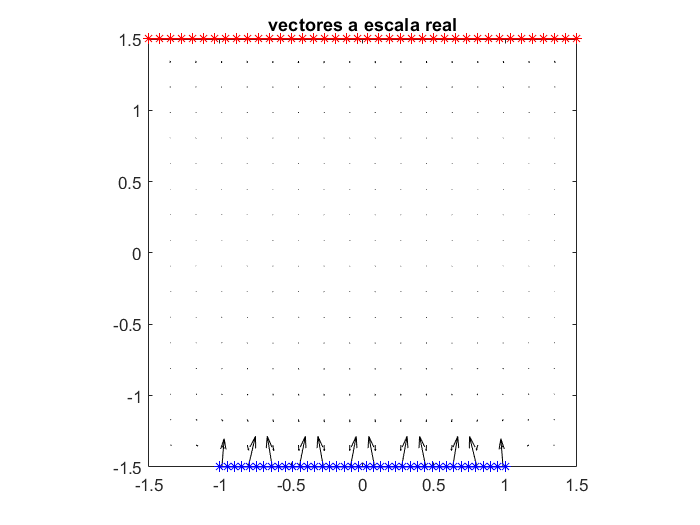

hold off


% Grafica con Stream slice
%subplot(1,3,3)
figure(3)
streamslice(X,Y,ex,ey)
axis equal
hold on
xlim([-size1/2-2,size1/2+2])
ylim([-sizey/2-1,sizey/2+1])
if qn1(1)>0
    fplot(f1,[-size1/2,size1/2],'r')
    plot(xqn1,yqn1,'r*')
    title('Lineas de campo electrico')
else
    fplot(f1,[-size1/2,size1/2],'b')
    plot(xqn1,yqn1,'b*')
    title('Lineas de campo electrico')
end


if qn2(1)>0
    plot(xqn2,yqn2,'r*')
    fplot(f2,[-(size2/2),size2/2],'r')
    title('Lineas de campo electrico')
else
    plot(xqn2,yqn2,'b*')
    fplot(f2,[-(size2/2),size2/2],'b')
    title('Lineas de campo electrico')
end

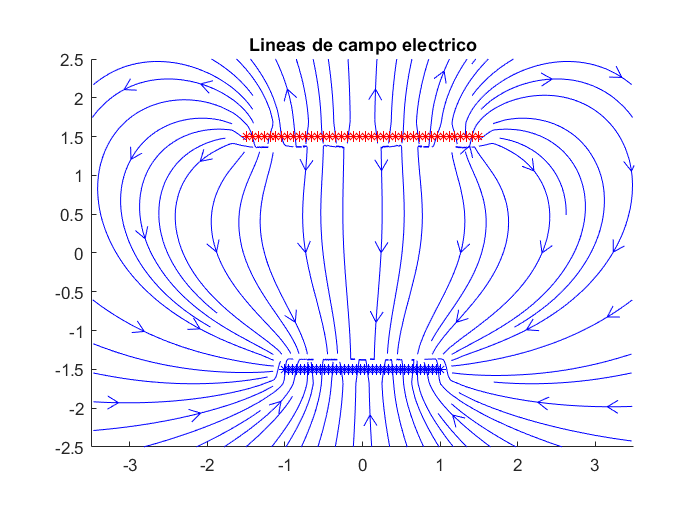

hold off